#### Image acquisition

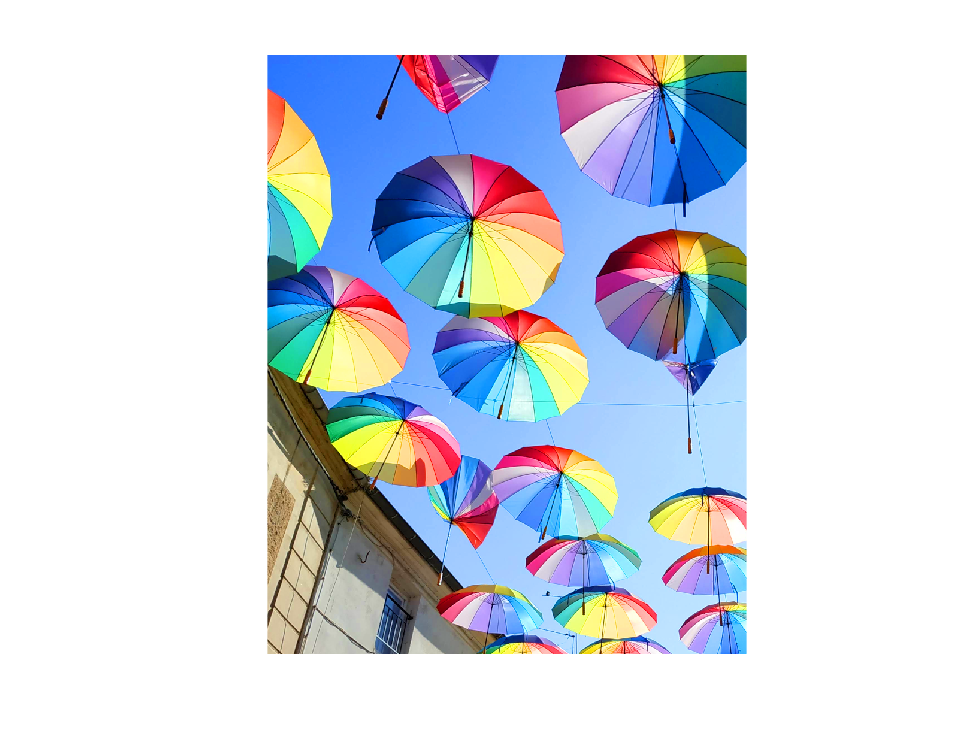

x=imread('colors.bmp');
figure;
image(x); axis image; axis off;

impixelinfo

#### Color channels

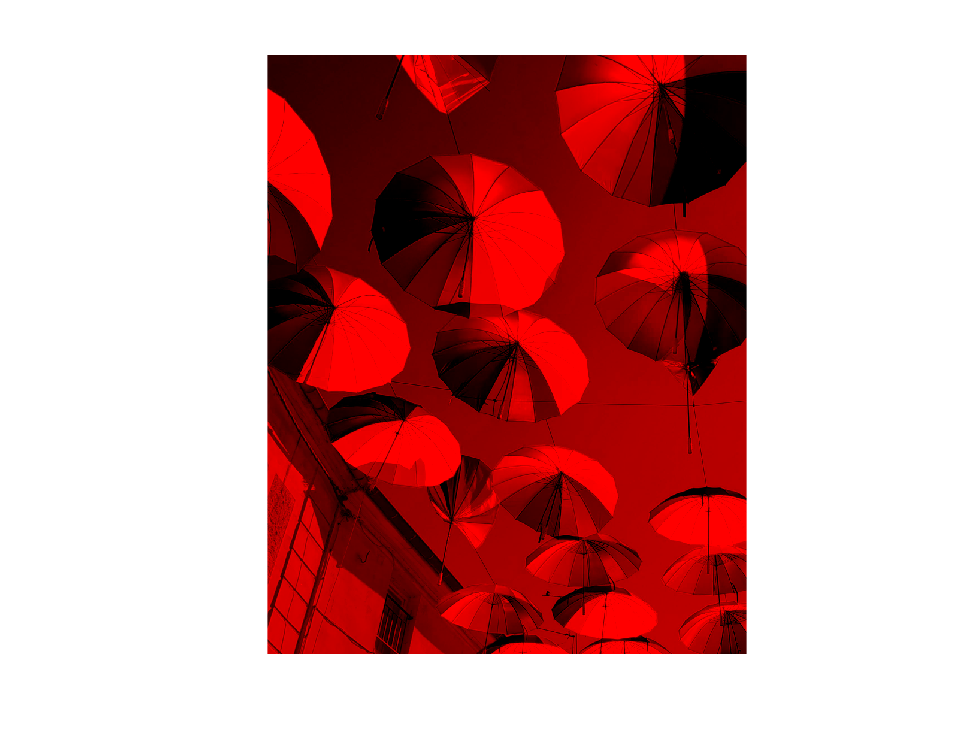

R = x(:,:,1);
G = x(:,:,2);
B = x(:,:,3);

figure;
levels = linspace(0,1,256);
cmapR=[levels',zeros(256,2)];
image(R); 
colormap(cmapR); axis image; axis off

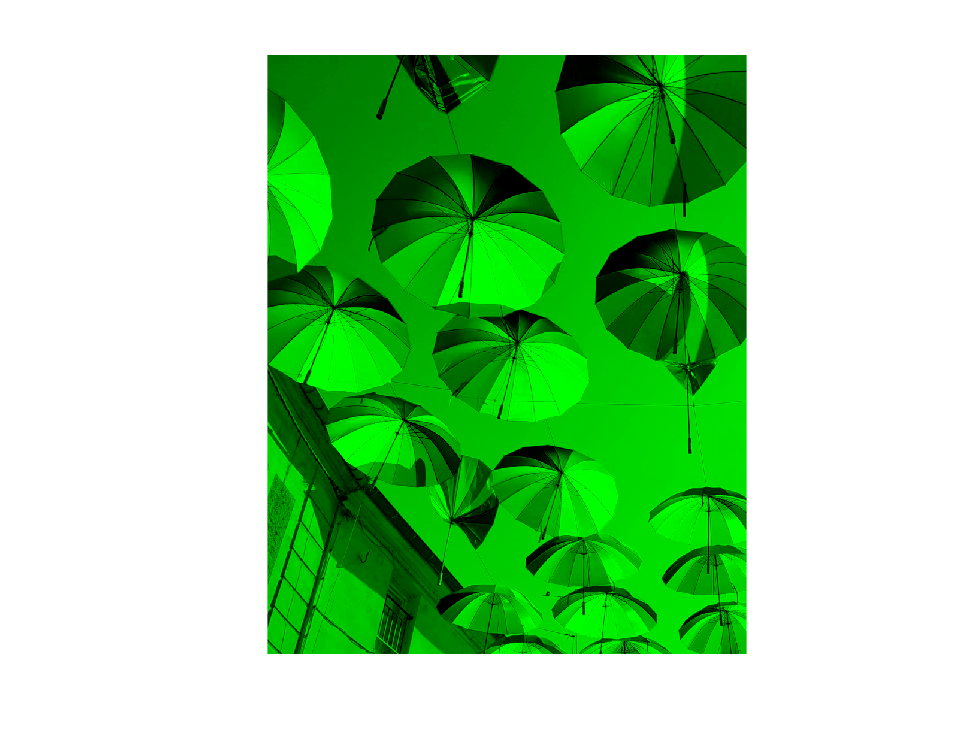



figure;
cmapG=[zeros(256,1), levels',zeros(256,1)];
image(G); 
colormap(cmapG); axis image; axis off

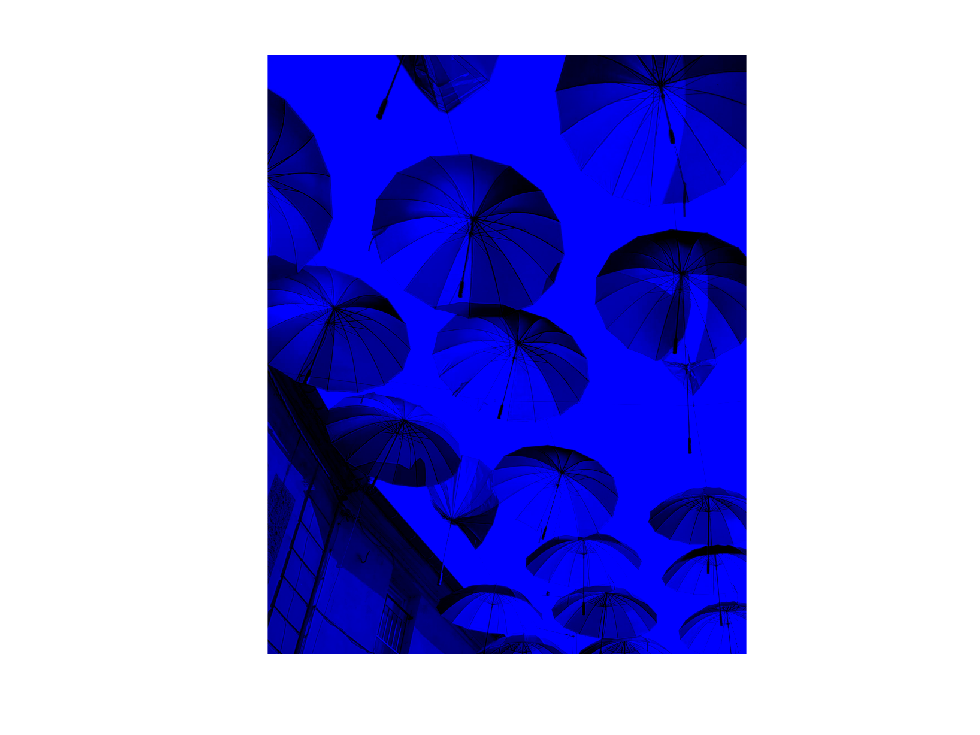



figure;
cmapB=[zeros(256,2),levels'];
image(B); 
colormap(cmapB); axis image; axis off

#### Color space transformation

YCbCr= rgb2ycbcr(x);
whos x YCbCr

  Name          Size                 Bytes  Class    Attributes

  YCbCr      1000x800x3            2400000  uint8              
  x          1000x800x3            2400000  uint8              



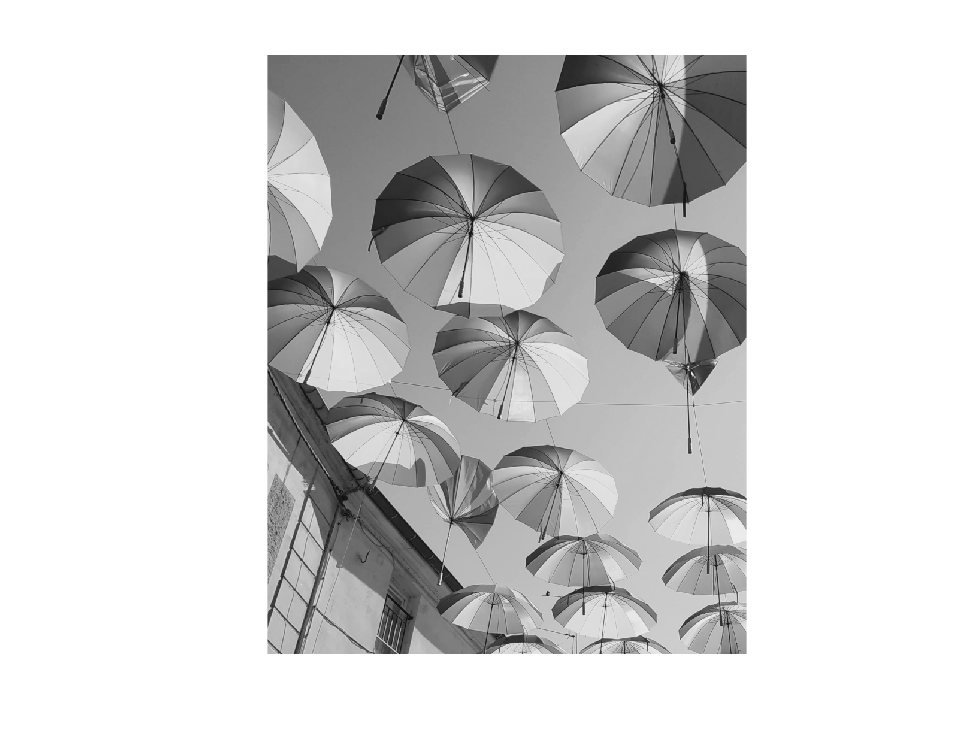


[N M C] = size(x);
Y = YCbCr(:,:,1);
Cb = YCbCr(:,:,2);
Cr = YCbCr(:,:,3);

figure;
image(Y); colormap("gray");
axis image; axis off;

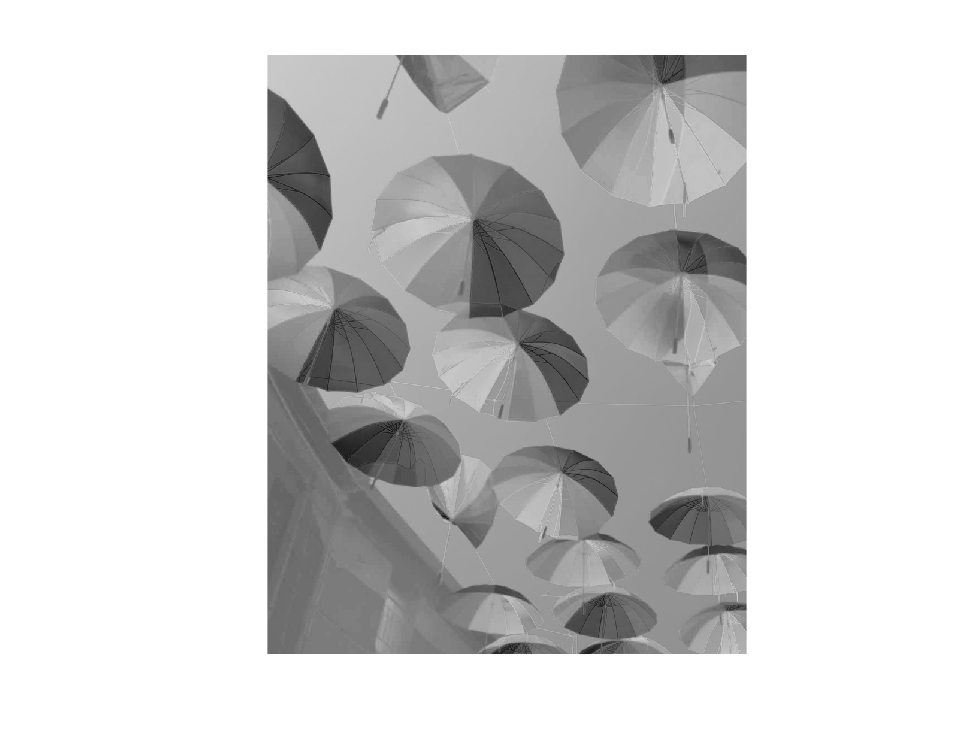



figure;
image(Cb); colormap("gray");
axis image; axis off;

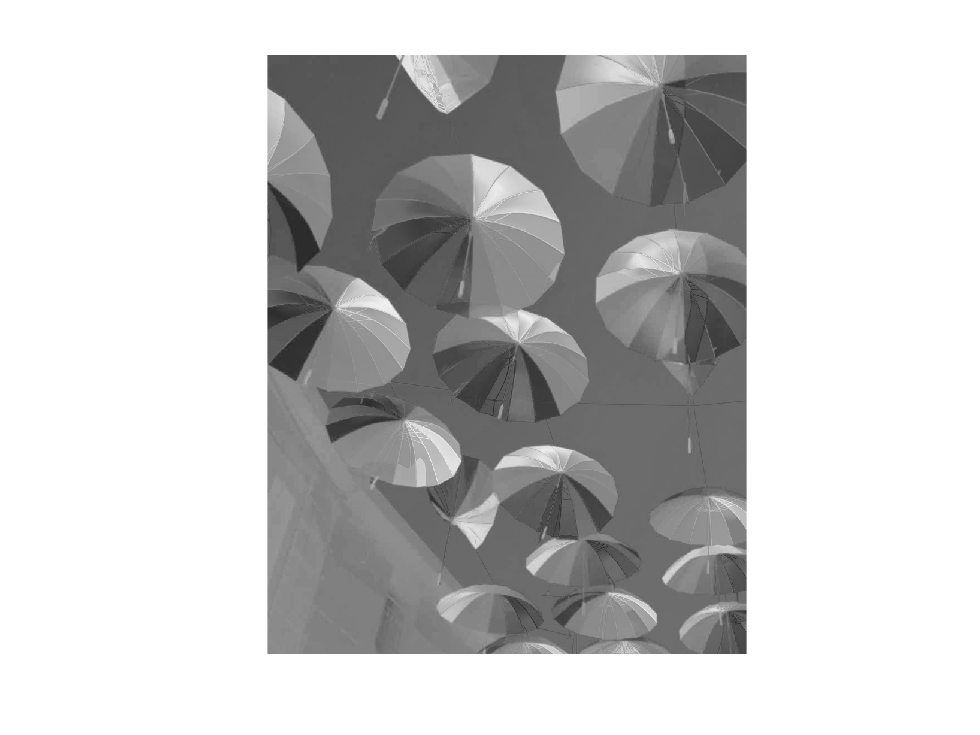



figure;
image(Cr); colormap("gray");
axis image; axis off;

#### Color subsampling

Cb2 = Cb(1:2:end,1:2:end);
Cr2 = Cr(1:2:end,1:2:end);

#### Writing on a file

fileName = 'test.ycbcr';
fid = fopen(fileName,'w');
fwrite(fid, Y(:),  "uint8");
fwrite(fid, Cb2(:),  "uint8");
fwrite(fid, Cr2(:),  "uint8");
fclose(fid);
size1 = dir('colors.bmp').bytes

size1 = 2400054

size2 = dir(fileName).bytes

size2 = 1200000

#### Back to the RGB space

CBInterp = zeros(size(Y));
CBInterp(1:2:end,1:2:end)= Cb2;
CBInterp(2:2:end,1:2:end)= Cb2;
CBInterp(1:2:end,2:2:end)= Cb2;
CBInterp(2:2:end,2:2:end)= Cb2;

CRInterp = zeros(size(Y));
CRInterp(1:2:end,1:2:end)= Cr2;
CRInterp(2:2:end,1:2:end)= Cr2;
CRInterp(1:2:end,2:2:end)= Cr2;
CRInterp(2:2:end,2:2:end)= Cr2;

YCbCrInterp=zeros(size(YCbCr));
YCbCrInterp(:,:,1) = Y;
YCbCrInterp(:,:,2) = CBInterp;
YCbCrInterp(:,:,3) = CRInterp;

RGB2 = ycbcr2rgb(uint8(YCbCrInterp));



error = double(x)-double(RGB2);
MSE = mean(error(:).^2)

MSE = 40.9427

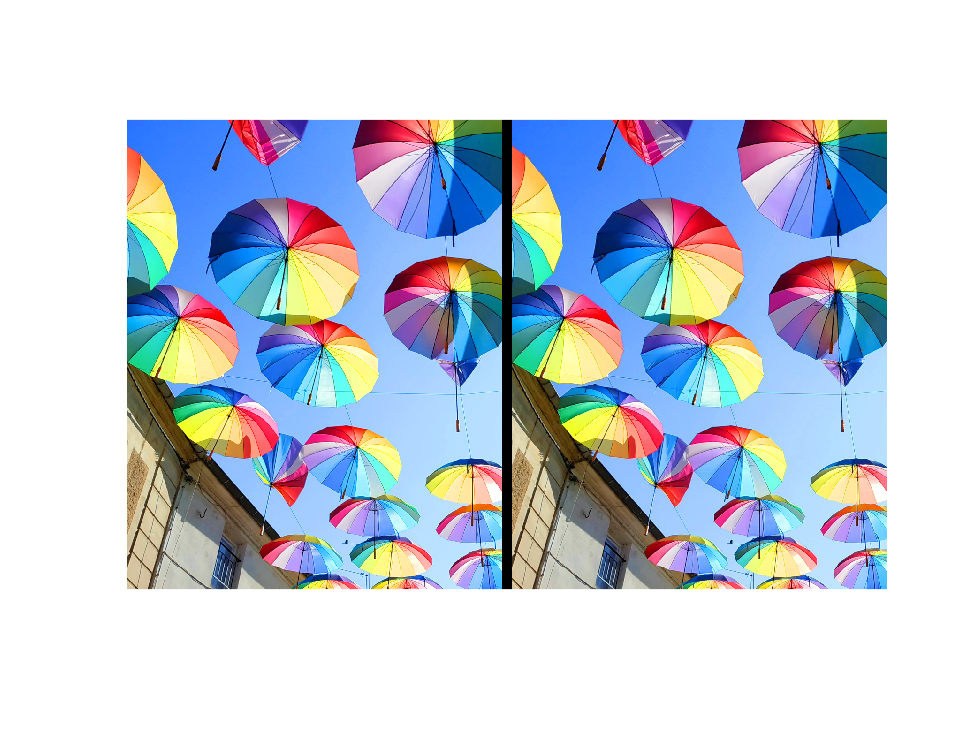


image([x, zeros(size(x,1),20,3), RGB2]);
axis image; axis off